Parameters was changed by Heesoo

%% define variables and ode settings
clc; clear;

% param = struct('m', 2, 'k', 134, 'c', 12, 'L', 0.6, 'g', 9.81);
param = struct('m', 2, 'k', 500, 'c', 20, 'L', 0.5, 'g', 9.81);

odeFun = @(~, y) systemOdeFun(y, param)

odeFun = function_handle with value:
    @(~,y)systemOdeFun(y,param)


odeJac = @(~, ~) systemOdeJac(param)

odeJac = function_handle with value:
    @(~,~)systemOdeJac(param)



% y0 = [0; 0; 1; 0.2]; % initial conditions
y0 = [0.01; pi()/6; 0; 0]; % initial conditions

dt = 1e-3;
tk = 2;
tic
[t, y] = odeBE(odeFun, [dt, tk], y0, odeJac);
toc

Elapsed time is 0.316867 seconds.


## plot results to see if they make sense

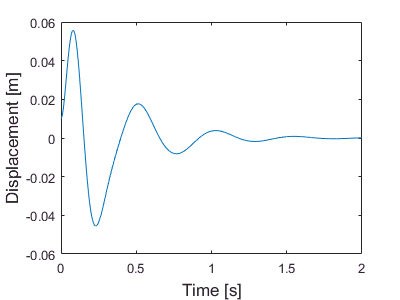

plot(t, y(:, 1)) 
set(gcf,'position',[5 5 400 300])
xlabel('Time [s]', 'Fontsize', 13);
ylabel('Displacement [m]', 'Fontsize', 13);
print('displacement','-dmeta')

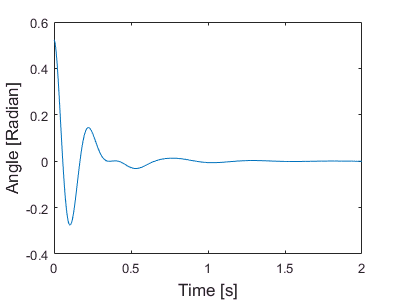

plot(t, y(:, 2)) 
set(gcf,'position',[5 5 400 300])
xlabel('Time [s]', 'Fontsize', 13);
ylabel('Angle [Radian]', 'Fontsize', 13);
print('Angle','-dmeta')

% point 4 done, but are results accurate?

%% check with shorter time step
divFactor = 4;
[t2, y2] = odeBE(odeFun, [dt/divFactor, tk], y0, odeJac);

disp('Compare odeBE with two different dt')

Compare odeBE with two different dt


compareResults( t, y, t2, y2 )

Diff in time: 0 rmse in Y1: 0.00034036 Y2: 0.0021893 Y3: 0.0075504 Y4: 0.06408


%% solve using ode15s
disp('ode15s default options')

ode15s default options


opts = odeset('AbsTol', 1e-9, 'RelTol', 1e-6);
tic
[t15s, y15s] = ode15s(odeFun, t, y0, opts);
toc

Elapsed time is 0.219937 seconds.


compareResults( t, y, t15s, y15s )

Diff in time: 0 rmse in Y1: 0.00045678 Y2: 0.002945 Y3: 0.010149 Y4: 0.086232



% 
disp('ode15s with Jacobian')

ode15s with Jacobian


opts = odeset(opts, 'Jacobian', odeJac);
tic
[t15sJ, y15sJ] = ode15s(odeFun, t, y0, opts);
toc

Elapsed time is 0.163151 seconds.


compareResults( t, y, t15sJ, y15sJ )

Diff in time: 0 rmse in Y1: 0.00045678 Y2: 0.002945 Y3: 0.010149 Y4: 0.086232



disp('Compare between ode15s-es')

Compare between ode15s-es


compareResults( t15s, y15s, t15sJ, y15sJ )

Diff in time: 0 rmse in Y1: 1.4298e-09 Y2: 1.3549e-08 Y3: 4.3882e-08 Y4: 4.1809e-07
